# Lab 7

#### Event selection optimization 

High $p_T$ dataset

Data setup...

h5disp("higgs_100000_pt_1000_1200.h5")

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5")

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


higgs = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
qcd = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

## 1. Stacked Histogram Plot for Mass

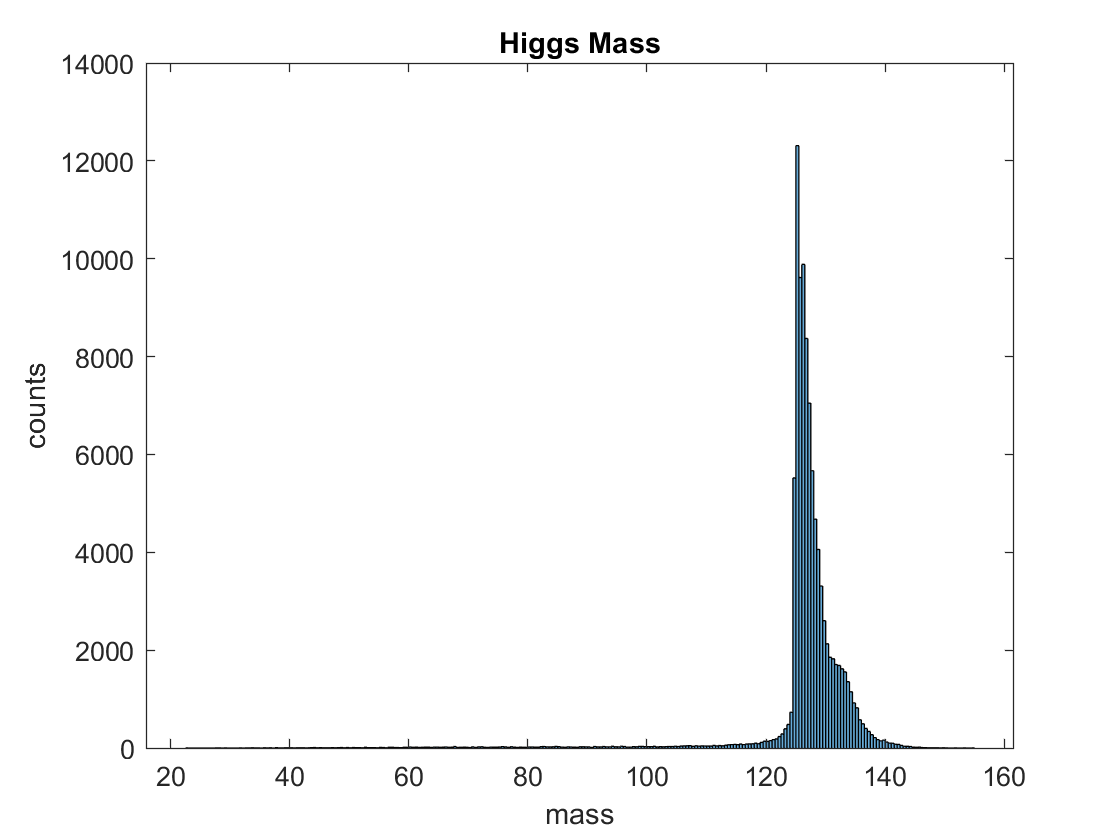

histogram(higgs(4,:));
title('Higgs Mass')
xlabel('mass')
ylabel('counts')

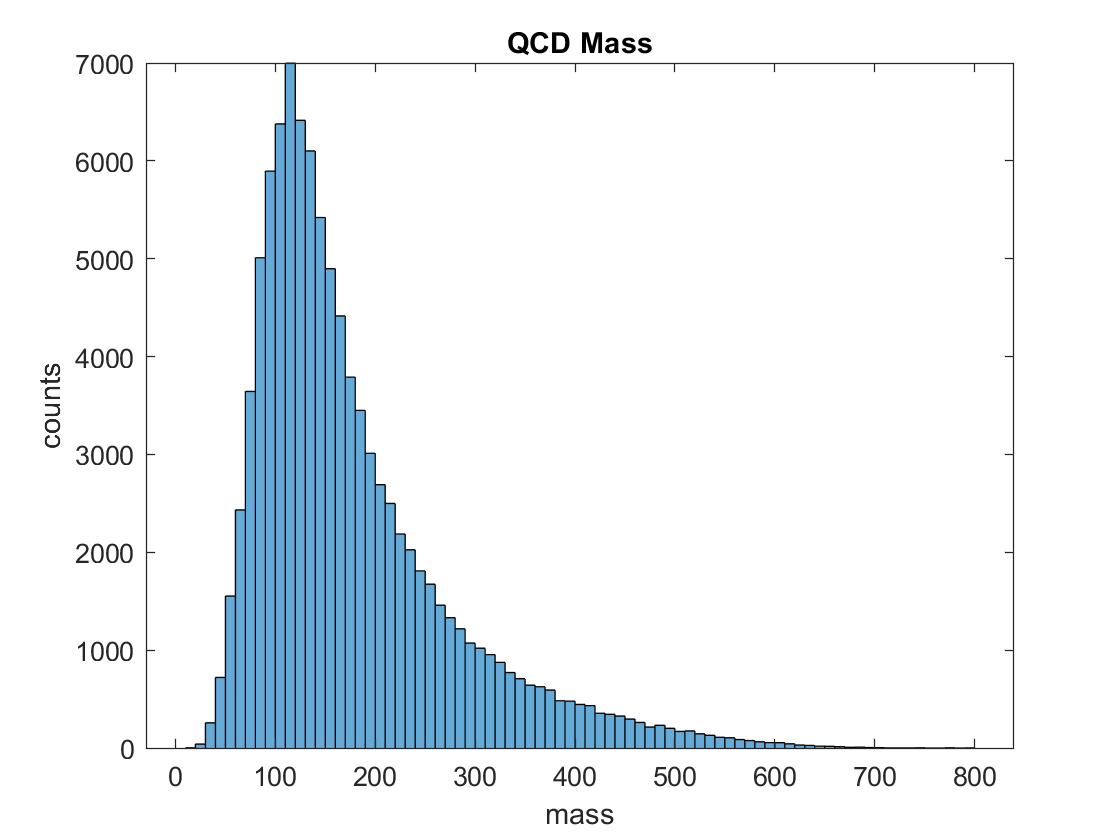

histogram(qcd(4,:));
title('QCD Mass')
xlabel('mass')
ylabel('counts')

Nhiggs = 50;
Nqcd = 2000;

### Evaluating base expected significance with Poisson statistics:

poiss = makedist('Poisson','lambda',2000);
signal = 2050;

pr = cdf(poiss,signal)

pr = 0.8704

sigma = norminv(pr)

sigma = 1.1282

### Comparison to the event number ratio:

ratio = Nhiggs/(sqrt(Nqcd))

ratio = 1.1180

The value of the ratio is very close to the calculated sigma value, with a difference of about 0.01. Therefore, I can use the ratio to calculate significance in my data. 

Number of events is a Poisson distribution with $\lambda$ equal to $N_{\mathrm{Higgs}} \;$or $N_{\mathrm{qcd}}$ so the ratio represents standard deviation. 

## 2. Identifying Mass Cuts to Optimize Significance

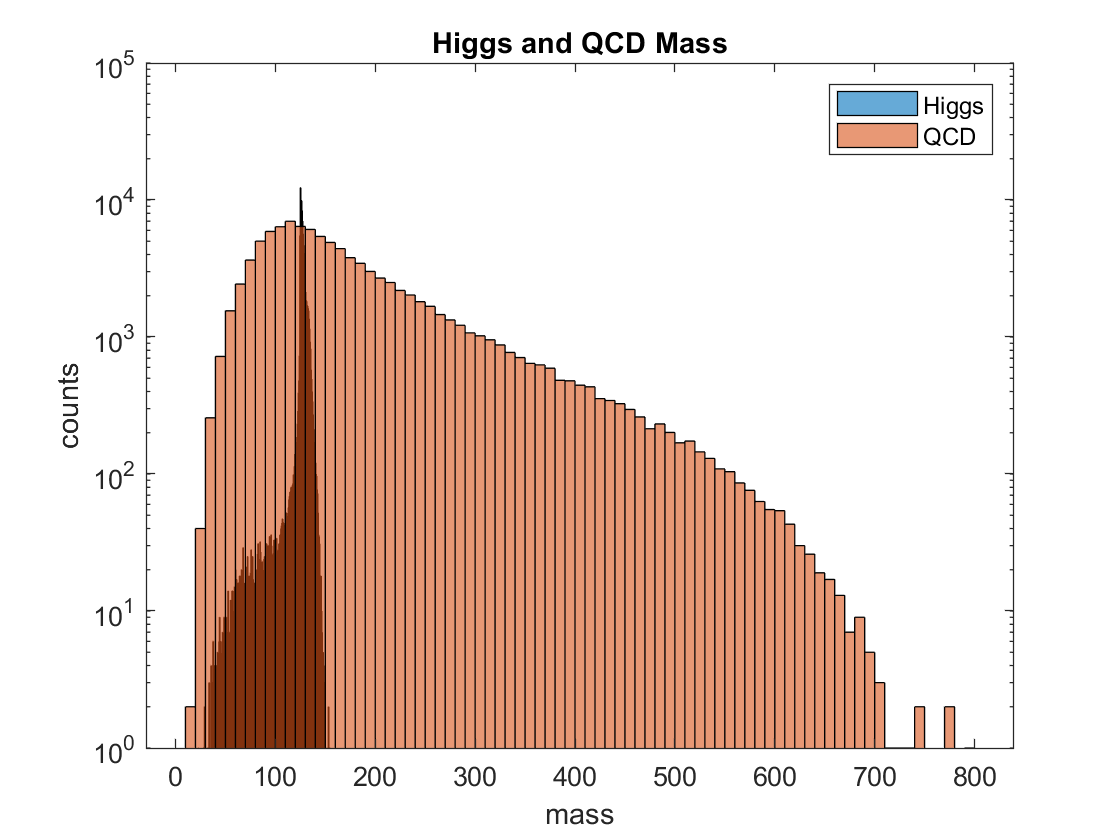

histogram(higgs(4,:));
hold on
histogram(qcd(4,:));
set(gca,'Yscale','log')
title('Higgs and QCD Mass')
xlabel('mass')
ylabel('counts')
legend('Higgs','QCD')
hold off

### Initial cut:

The majority of the Higgs data runs from about 100 to 140, so I'll use those values for my initial cut limits. I'm using a for loop to cut my data and assigning a value of 1 to the data within [100,140] and a value of 0 to the data outside of it, with all values saved two vectors (one for each dataset). Using the 0s and 1s, the sum of each vector will give me the number of datapoints within my range, and I can use that value to scale down $N_{\mathrm{Higgs}}$ and $N_{\mathrm{qcd}}$ appropriately. I will then calculate my expected significance with the ratio $\frac{N_{\mathrm{Higgs}} }{\sqrt{N_{\mathrm{qcd}} }}$.  

l = length(higgs(4,:));
hcount = zeros(1,l);

for i = 1:l
    if (100 < higgs(4,i)) && (higgs(4,i) < 140)
        hcount(i) = 1;
    else
        hcount(i) = 0;
    end
end

Nhiggs = sum(hcount)*50/l

Nhiggs = 48.6715


bcount = zeros(1,l);

for i = 1:l
    if (100 < qcd(4,i)) && (qcd(4,i) < 140)
        bcount(i) = 1;
    else
        bcount(i) = 0;
    end
end

Nqcd = sum(bcount)*2000/l

Nqcd = 517.8000

significance = Nhiggs/(sqrt(Nqcd))

significance = 2.1389

With my initial cut, the significance already increases a full sigma.

### Systematic cuts:

My systematic cuts use the same method as above, with additional for loops to run through all potential value ranges. 

step = 0.5;
maxh = 127;
j = 100:step:maxh;
k = (maxh + step):step:140;
J = length(j);
K = length(k);


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(4,i)) && (higgs(4,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(4,p)) && (qcd(4,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

M = zeros(1,14);

[A,B] = max(sigs,[],"all",'linear');
M(4) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 4.4627

coords = zeros(14,2);
coords(4,1) = j(b);
coords(4,2) = k(a);

So the interval resulting in the maximum significance, $4\ldotp 46\sigma$, is $124\ldotp 5\le \mathrm{mass}\le 138\ldotp 5$. 

Here's the representative histogram:

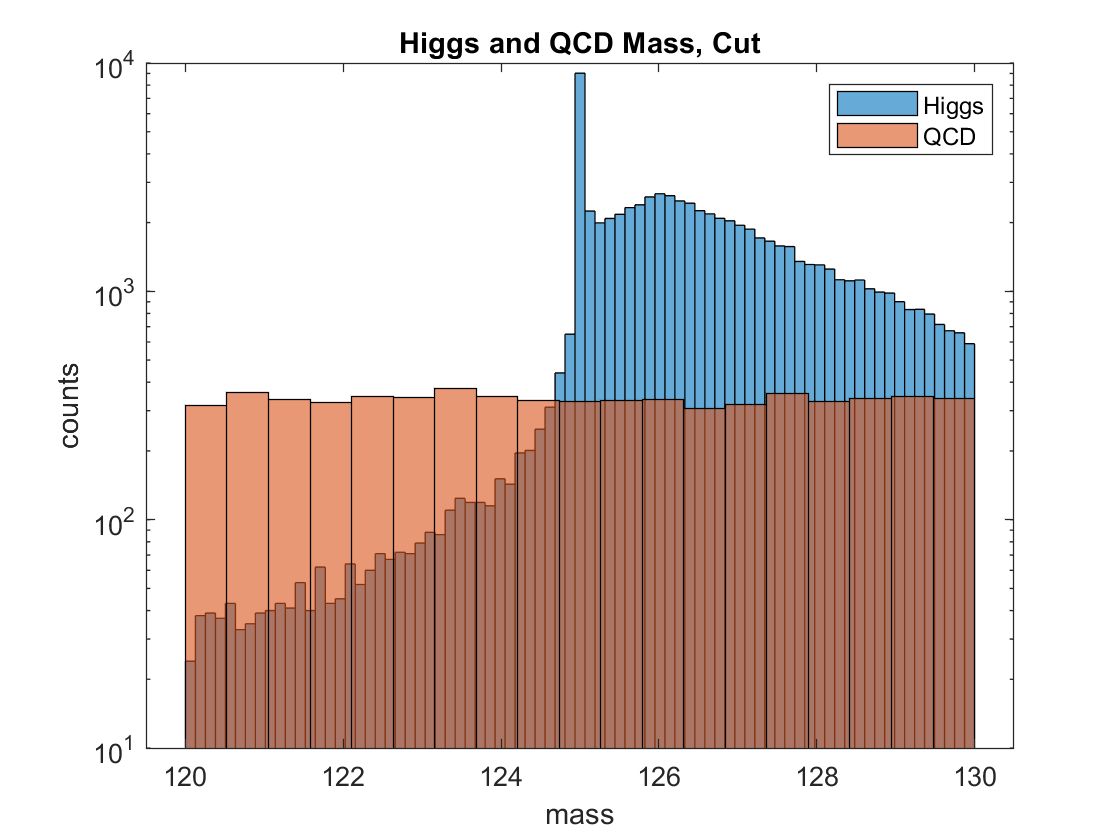

histogram(higgs(4,:),'BinLimits',[120,130]);
hold on
histogram(qcd(4,:),'BinLimits',[120,130]);
set(gca,'Yscale','log')
title('Higgs and QCD Mass, Cut')
xlabel('mass')
ylabel('counts')
legend('Higgs','QCD')
hold off

## 3. Histograms for the Rest of the Features

### No event selection:

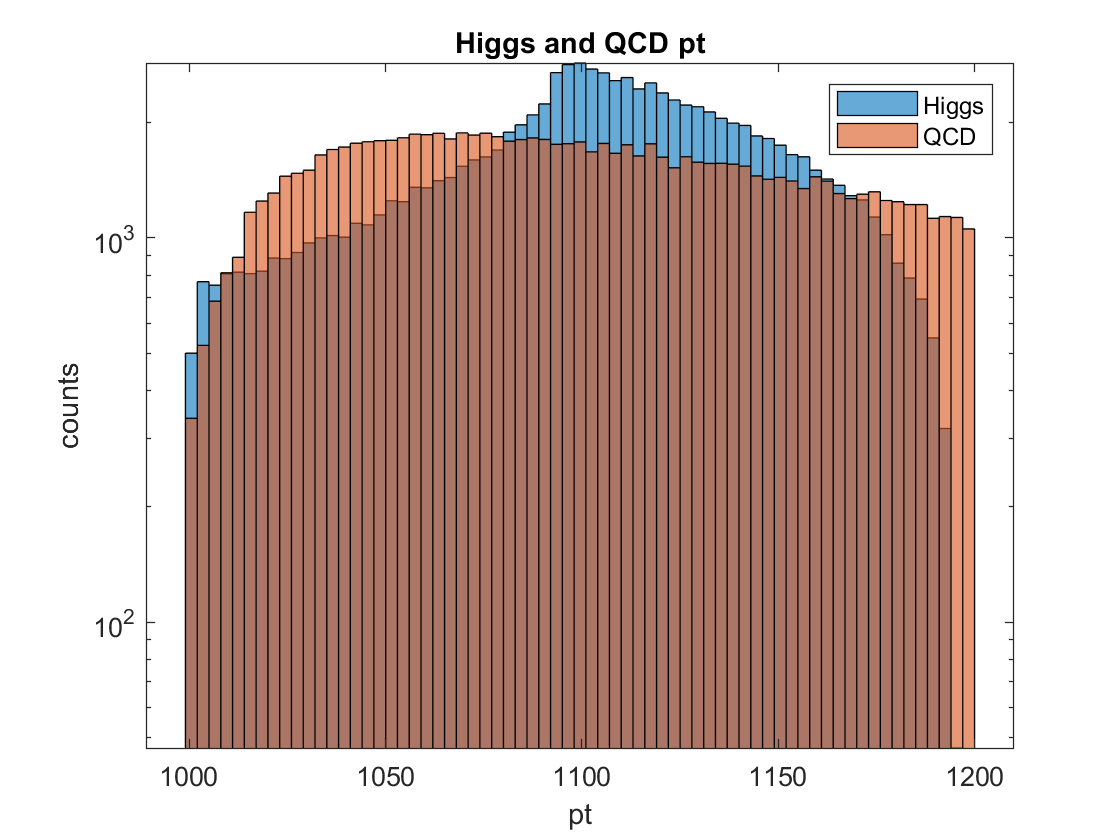

%pt
histogram(higgs(1,:));
hold on
histogram(qcd(1,:));
set(gca,'Yscale','log')
title('Higgs and QCD pt')
xlabel('pt')
ylabel('counts')
legend('Higgs','QCD')
hold off

%eta
histogram(higgs(2,:));
hold on
histogram(qcd(2,:));
set(gca,'Yscale','log')
title('Higgs and QCD eta')
xlabel('eta')
ylabel('counts')
legend('Higgs','QCD')
hold off

%phi
histogram(higgs(3,:));
hold on
histogram(qcd(3,:));
set(gca,'Yscale','log')
title('Higgs and QCD phi')
xlabel('phi')
ylabel('counts')
legend('Higgs','QCD')
hold off

%ee2
histogram(higgs(5,:));
hold on
histogram(qcd(5,:));
set(gca,'Yscale','log')
title('Higgs and QCD ee2')
xlabel('ee2')
ylabel('counts')
legend('Higgs','QCD')
hold off

%ee3
histogram(higgs(6,:));
hold on
histogram(qcd(6,:));
set(gca,'Yscale','log')
title('Higgs and QCD ee3')
xlabel('ee3')
ylabel('counts')
legend('Higgs','QCD')
hold off

%d2
histogram(higgs(7,:));
hold on
histogram(qcd(7,:));
set(gca,'Yscale','log')
title('Higgs and QCD d2')
xlabel('d2')
ylabel('counts')
legend('Higgs','QCD')
hold off

%angularity
histogram(higgs(8,:));
hold on
histogram(qcd(8,:));
set(gca,'Yscale','log')
title('Higgs and QCD angularity')
xlabel('angularity')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t1
histogram(higgs(9,:));
hold on
histogram(qcd(9,:));
set(gca,'Yscale','log')
title('Higgs and QCD t1')
xlabel('t1')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t2
histogram(higgs(10,:));
hold on
histogram(qcd(10,:));
set(gca,'Yscale','log')
title('Higgs and QCD t2')
xlabel('t2')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t3
histogram(higgs(11,:));
hold on
histogram(qcd(11,:));
set(gca,'Yscale','log')
title('Higgs and QCD t3')
xlabel('t3')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t21
histogram(higgs(12,:));
hold on
histogram(qcd(12,:));
set(gca,'Yscale','log')
title('Higgs and QCD t21')
xlabel('t21')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t32
histogram(higgs(13,:));
hold on
histogram(qcd(13,:));
set(gca,'Yscale','log')
title('Higgs and QCD t32')
xlabel('t32')
ylabel('counts')
legend('Higgs','QCD')
hold off

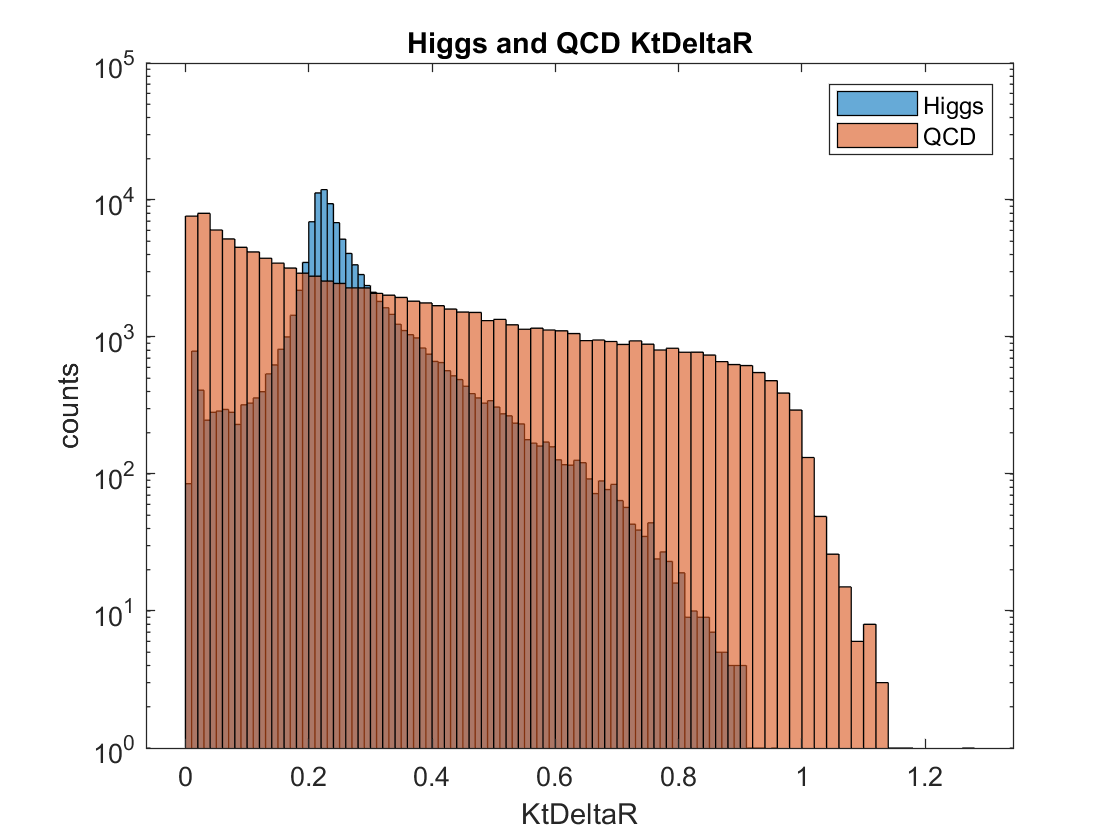

%KtDeltaR
histogram(higgs(14,:));
hold on
histogram(qcd(14,:));
set(gca,'Yscale','log')
title('Higgs and QCD KtDeltaR')
xlabel('KtDeltaR')
ylabel('counts')
legend('Higgs','QCD')
hold off

### Significance calculations and optimized histograms:

%pt
step = 5;
maxh = 1075;
j = 1000:step:maxh;
k = (maxh + step):step:1200;
J = length(j);
K = length(k);
r = 1;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 1.1334

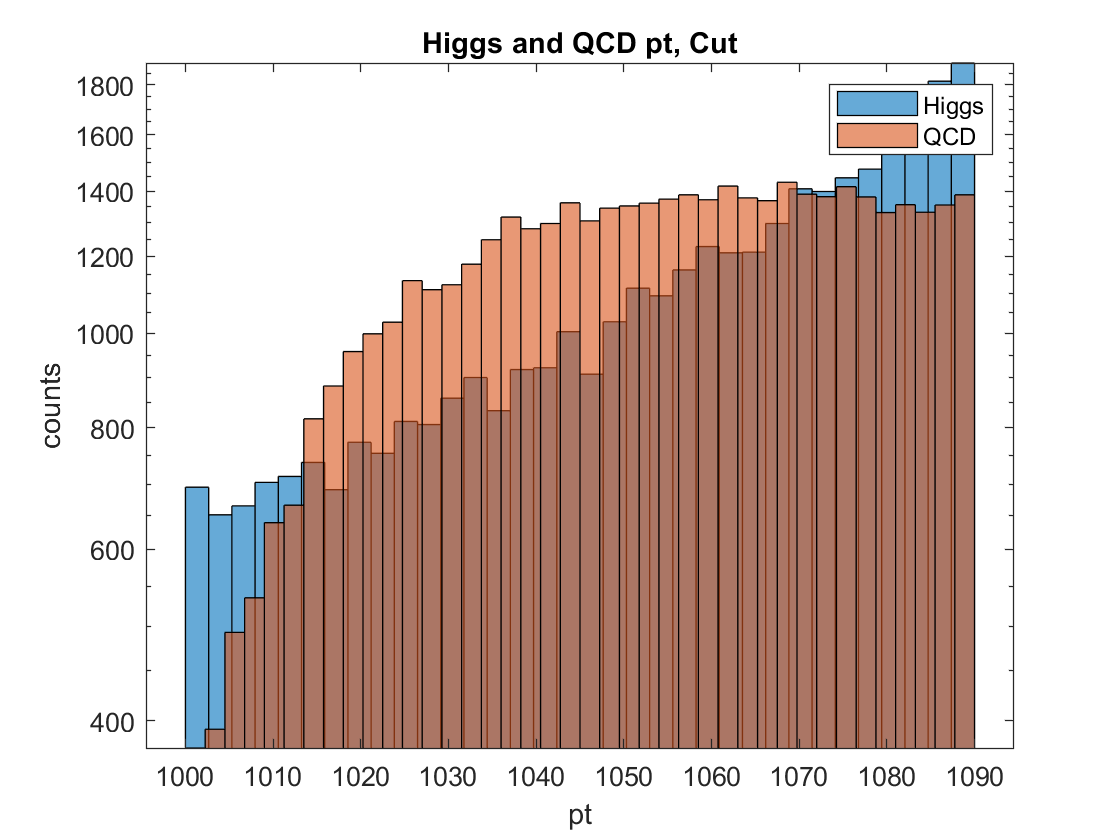

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD pt, Cut')
xlabel('pt')
ylabel('counts')
legend('Higgs','QCD')
hold off

%eta
step = 0.1;
maxh = -0.8;
j = -2:step:maxh;
k = (maxh + step):step:2;
J = length(j);
K = length(k);
r = 2;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans = 1.2092

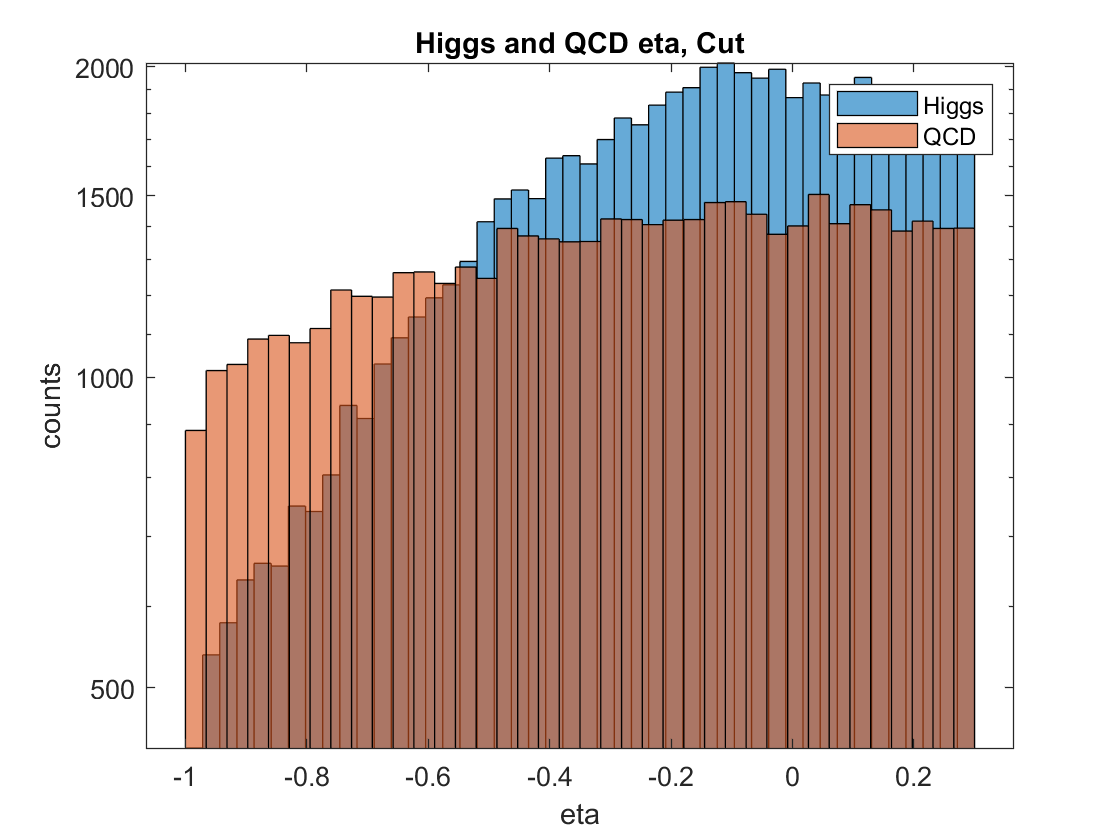

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD eta, Cut')
xlabel('eta')
ylabel('counts')
legend('Higgs','QCD')
hold off

%phi
step = 0.1;
maxh = -2.6;
j = -3:step:maxh;
k = (maxh + step):step:3;
J = length(j);
K = length(k);
r = 3;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
if a == 0
    a = 1;
end
sigs(b,a)

ans = 1.0922

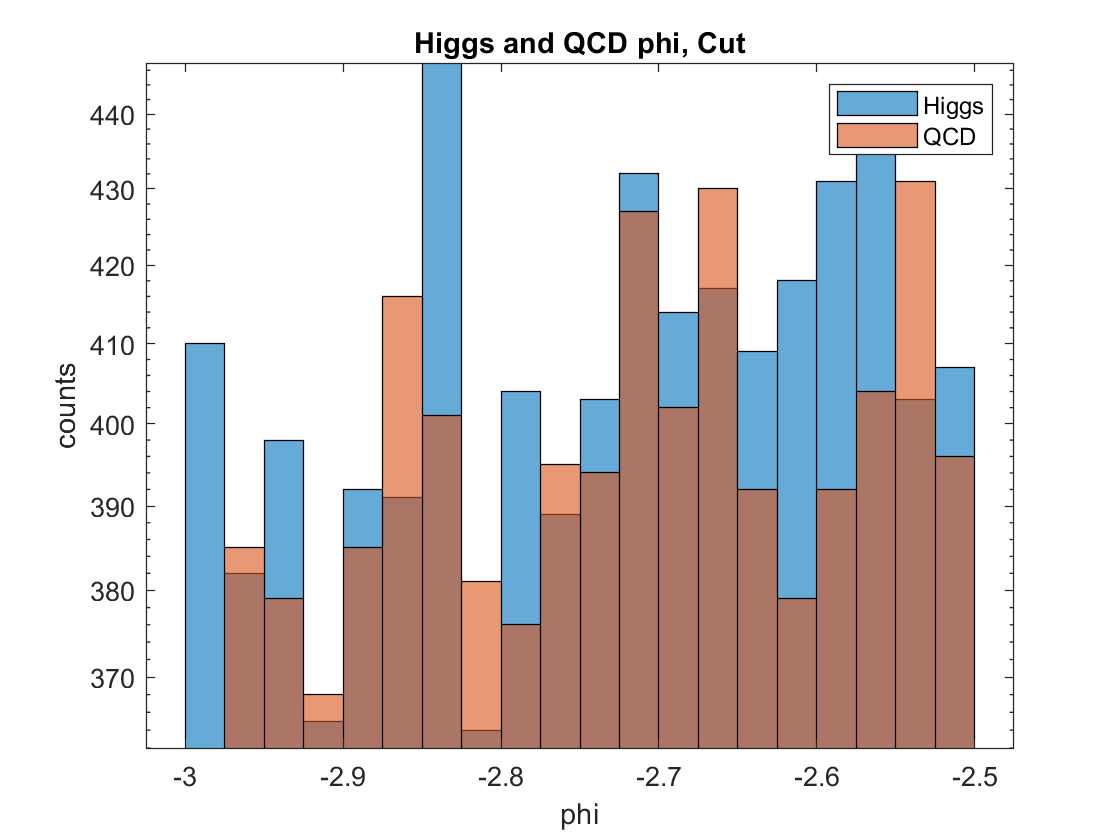

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD phi, Cut')
xlabel('phi')
ylabel('counts')
legend('Higgs','QCD')
hold off

%ee2
step = 0.005;
maxh = 0.06;
j = 0:step:maxh;
k = (maxh + step):step:0.2;
J = length(j);
K = length(k);
r = 5;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans =    2.112906575899846


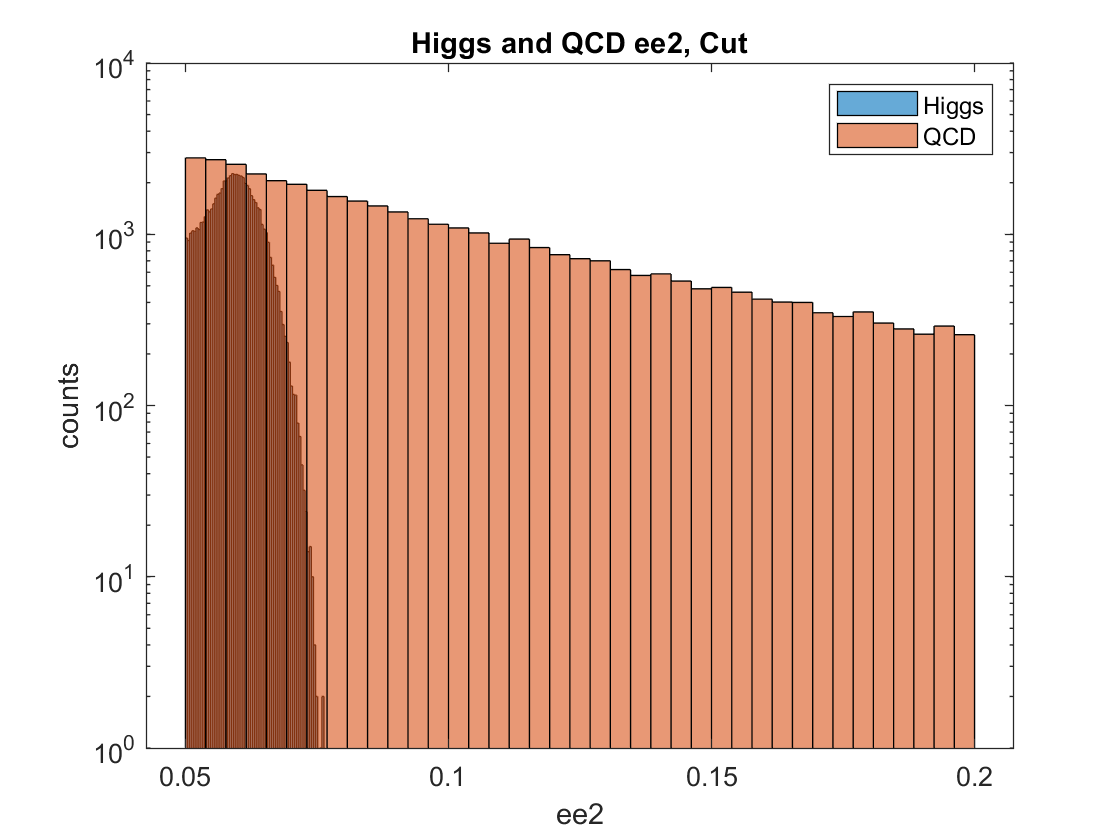

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD ee2, Cut')
xlabel('ee2')
ylabel('counts')
legend('Higgs','QCD')
hold off

%ee3
step = 0.001;
maxh = 0.01;
j = 0:step:maxh;
k = (maxh + step):step:0.07;
J = length(j);
K = length(k);
r = 6;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans =    1.133288727966817


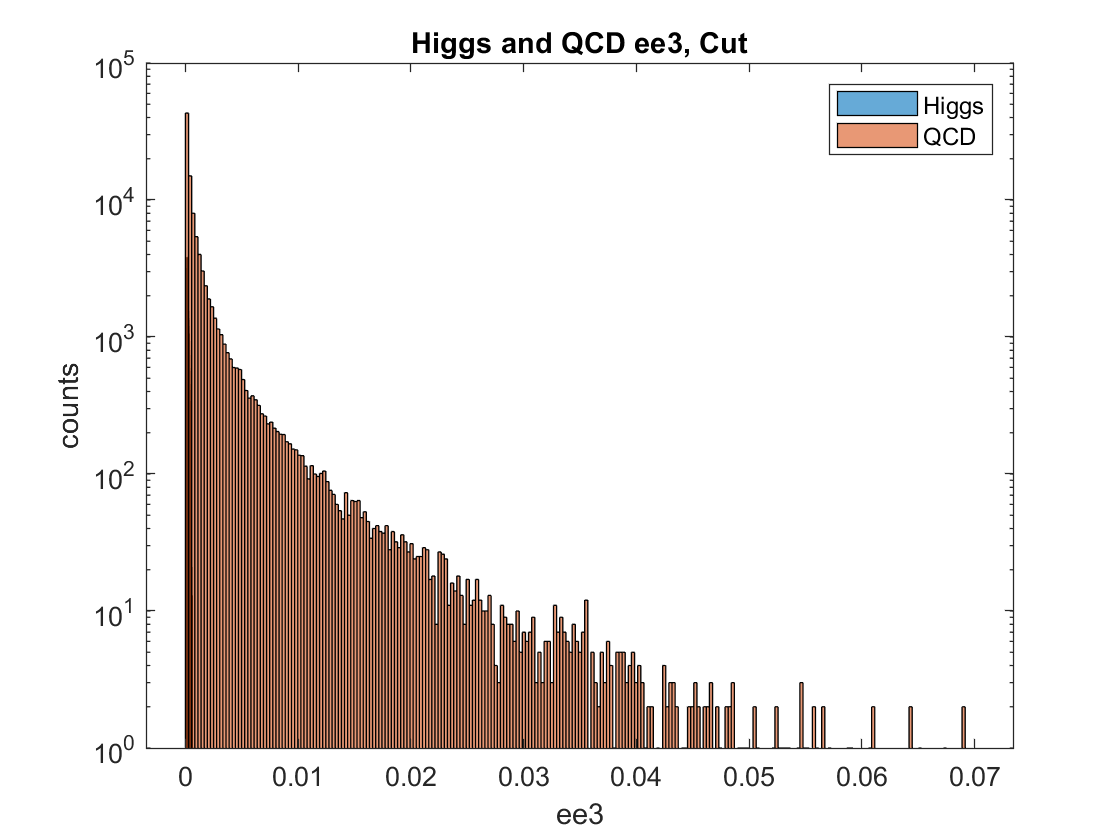

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD ee3, Cut')
xlabel('ee3')
ylabel('counts')
legend('Higgs','QCD')
hold off

%d2
step = 0.05;
maxh = 0.05;
j = 0;
k = (maxh + step):step:100;
J = length(j);
K = length(k);
r = 7;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans =    2.035748024551349


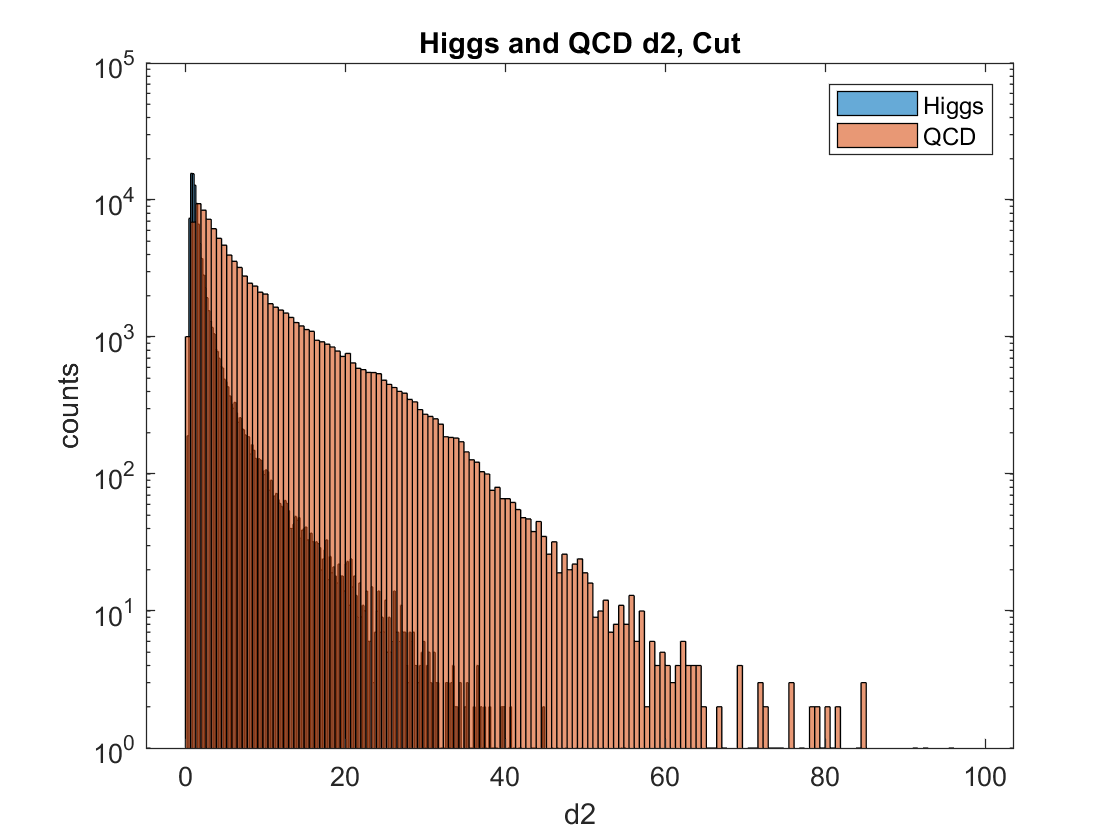

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD d2, Cut')
xlabel('d2')
ylabel('counts')
legend('Higgs','QCD')
hold off

%angularity
step = 0.001;
maxh = 0.001;
j = 0;
k = (maxh + step):step:0.3;
J = length(j);
K = length(k);
r = 8;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
if a ==0
    a = 1;
end
sigs(b,a)

ans =    1.653485013957087


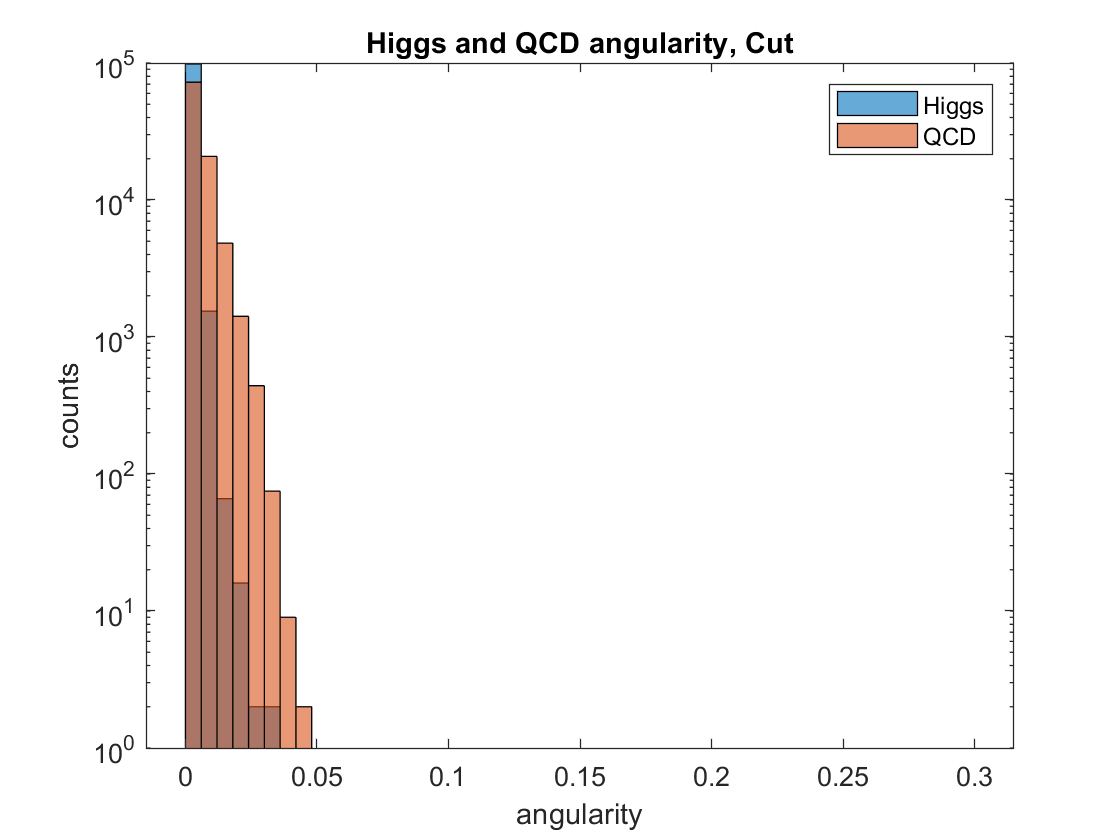

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)],'NumBins',50);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)],'NumBins',50);
set(gca,'Yscale','log')
title('Higgs and QCD angularity, Cut')
xlabel('angularity')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t1
step = 0.01;
maxh = 0.7;
j = 0.5:step:maxh;
k = (maxh + step):step:3;
J = length(j);
K = length(k);
r = 9;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans =    1.119658811398854


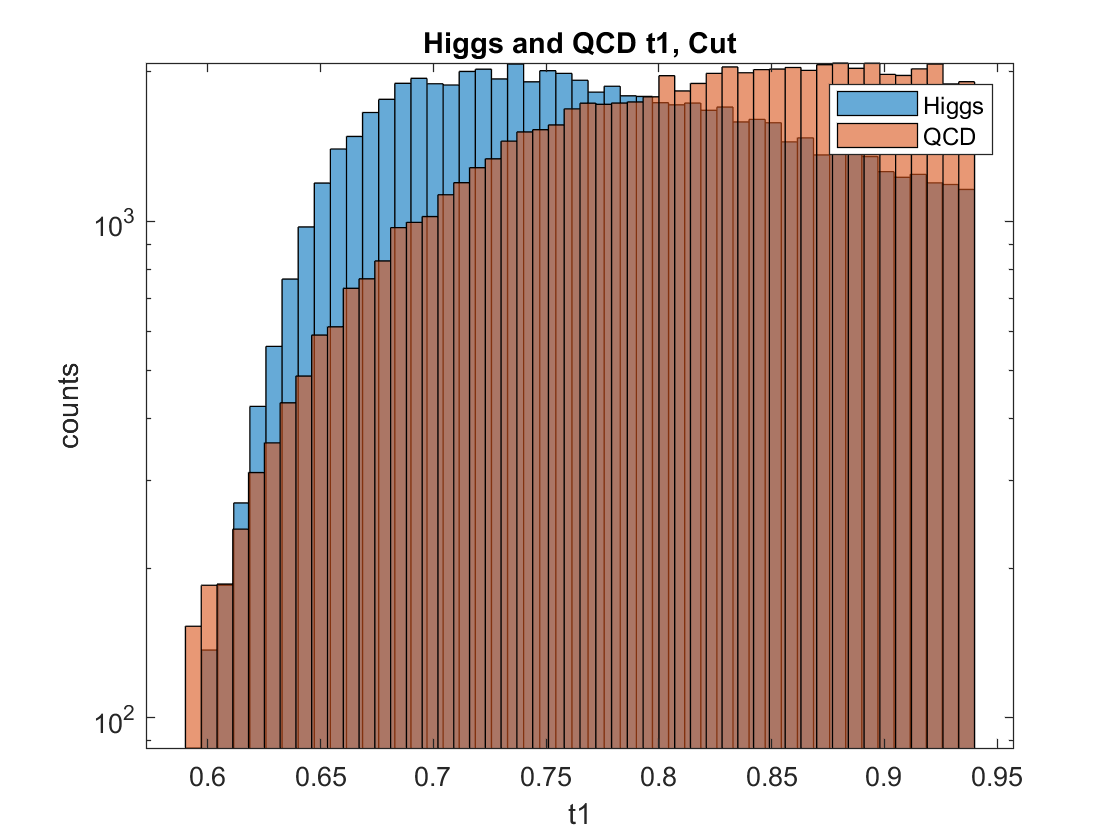

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD t1, Cut')
xlabel('t1')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t2
step = 0.01;
maxh = 0.15;
j = 0:step:maxh;
k = (maxh + step):step:1;
J = length(j);
K = length(k);
r = 10;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans =    1.846794192636700


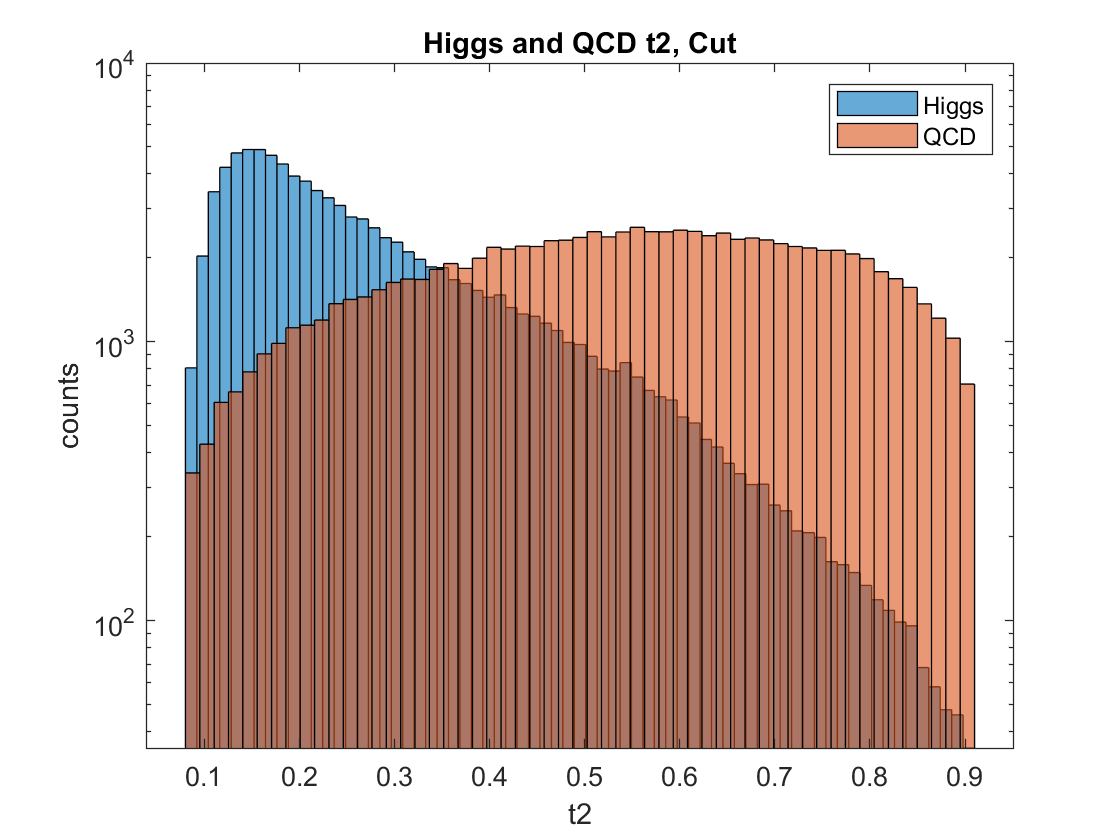

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD t2, Cut')
xlabel('t2')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t3
step = 0.01;
maxh = 0.15;
j = 0:step:maxh;
k = (maxh + step):step:1;
J = length(j);
K = length(k);
r = 11;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans =    1.861229607189965


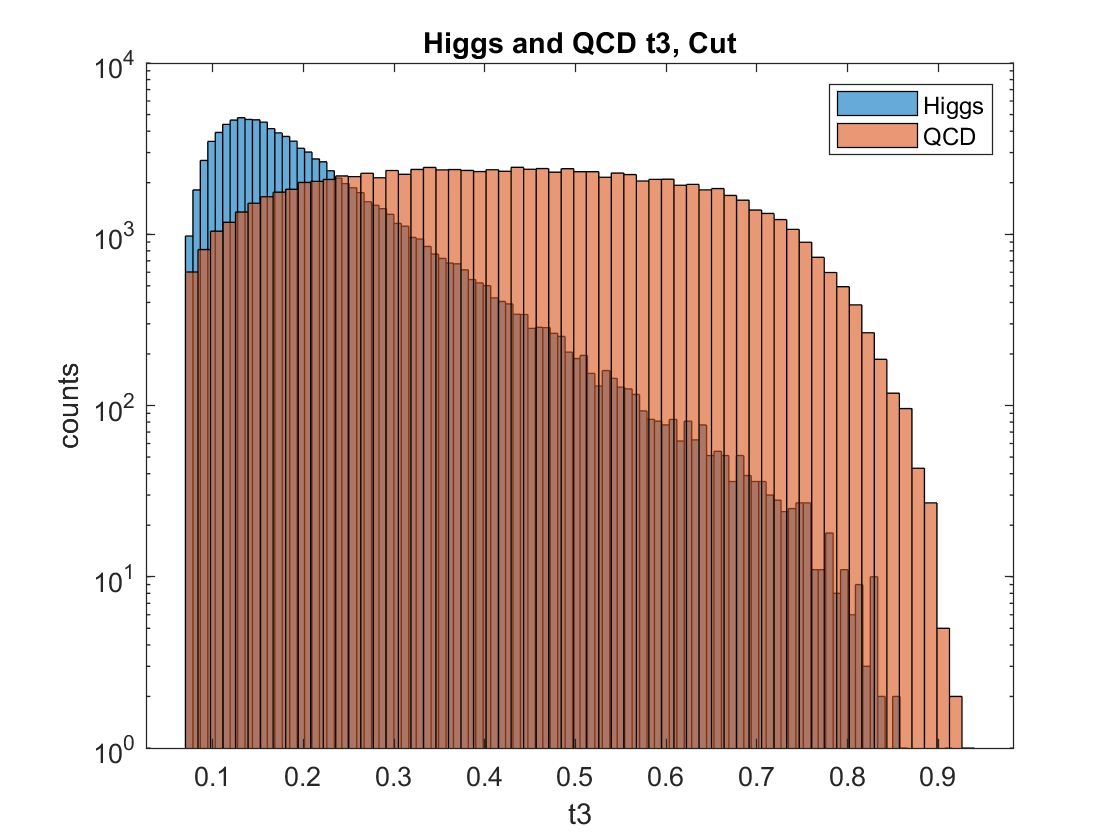

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD t3, Cut')
xlabel('t3')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t21
step = 0.01;
maxh = 0.17;
j = 0:step:maxh;
k = (maxh + step):step:1;
J = length(j);
K = length(k);
r = 12;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans =    1.825810340599588


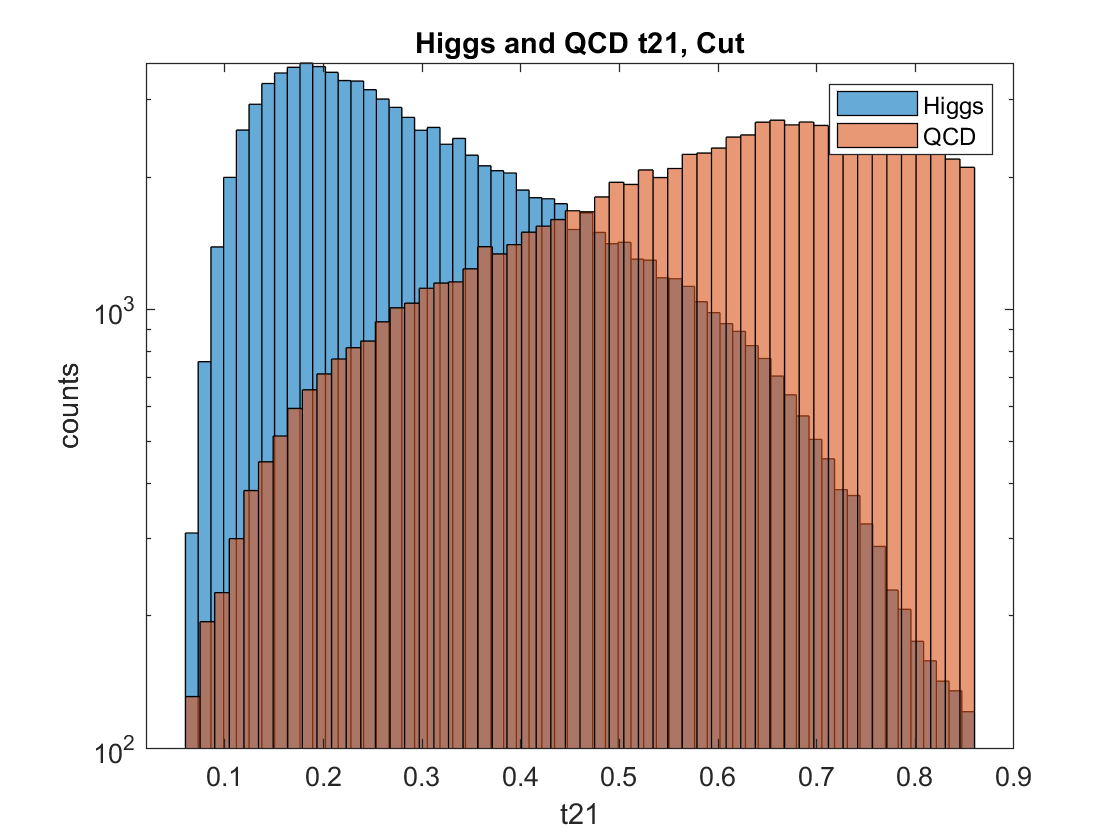

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD t21, Cut')
xlabel('t21')
ylabel('counts')
legend('Higgs','QCD')
hold off

%t32
step = 0.01;
maxh = 0.5;
j = 0:step:maxh;
k = (maxh + step):step:1;
J = length(j);
K = length(k);
r = 13;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans =    1.129869055257240


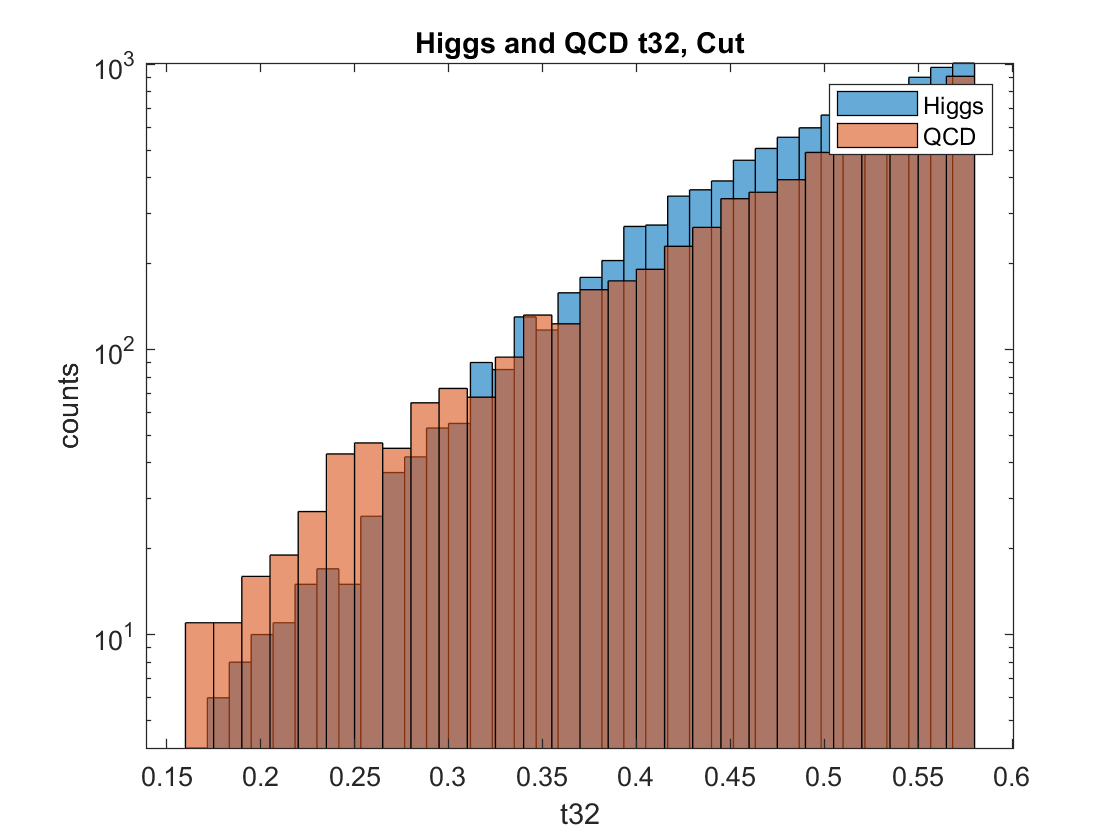

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD t32, Cut')
xlabel('t32')
ylabel('counts')
legend('Higgs','QCD')
hold off

%KtDeltaR
step = 0.01;
maxh = 0.21;
j = 0:step:maxh;
k = (maxh + step):step:1;
J = length(j);
K = length(k);
r = 14;


sigs = zeros(length(j),length(k));
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(r,i)) && (higgs(r,i) < k(K-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(r,p)) && (qcd(r,p) < k(K-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
M(r) = A;
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans =    2.077712167716375


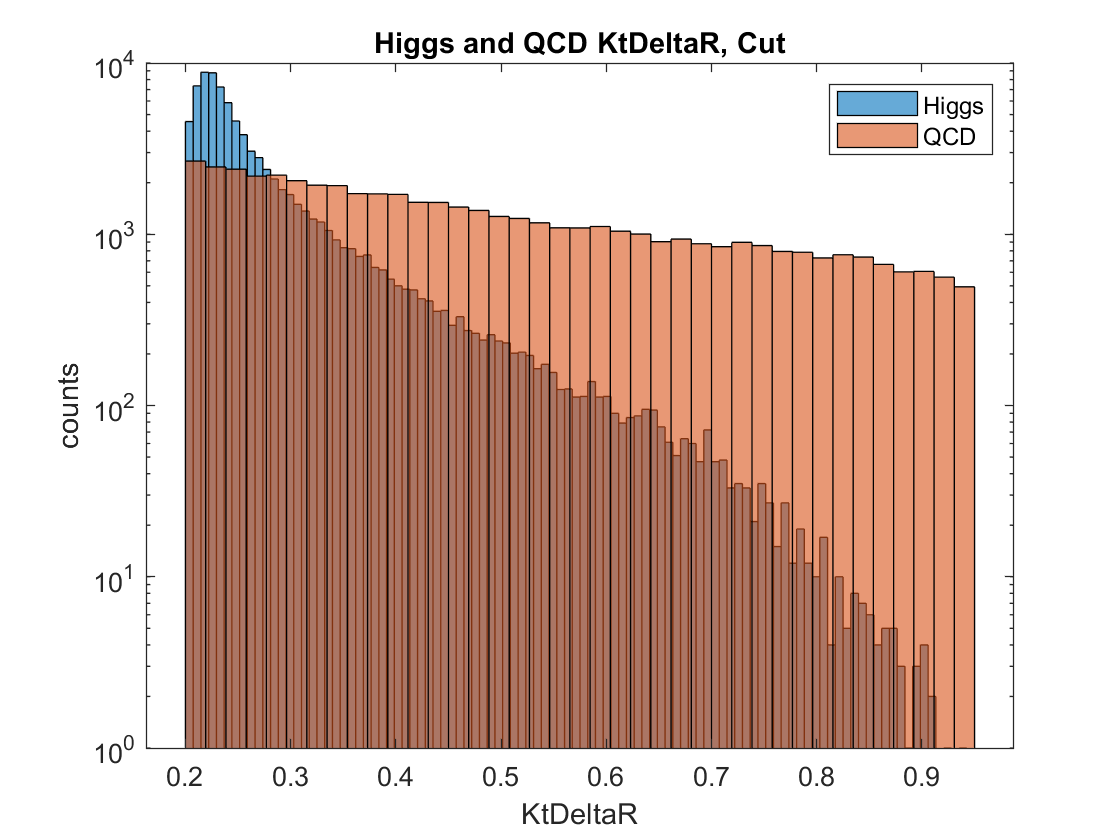

coords(r,1) = j(b);
coords(r,2) = k(a);

histogram(higgs(r,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(r,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD KtDeltaR, Cut')
xlabel('KtDeltaR')
ylabel('counts')
legend('Higgs','QCD')
hold off

coords

M

M =    1.133388103738003   1.209233012159161   1.092233959428455   4.462737458420730   2.112906575899846   1.133288727966817   2.035748024551349   1.653485013957087   1.119658811398854   1.846794192636700   1.861229607189965   1.825810340599588   1.129869055257240   2.077712167716375


None of the other features are as discerning as the mass plot, but the feature with the highest significance after mass is ee2, with a maximum significance of about $2\ldotp 1\sigma$. 

Mass and ee2 together could potentially improve significance.

## 4. Multi-Feature Event Selection Optimization

Here I'm using both mass and ee2 to increase significance. I'm doing this by further limiting data selection with limits on mass and ee2 (seen in the 'if' section of the for loop). 

j = 102:0.25:127;
k = 127.4:0.1:140.9;
J = length(j);
K = length(k);


q = 0:0.0006:0.06;
s = 0.065:0.001:0.2;
Q = length(q);
S = length(s);



sigs = zeros(J,K);
hcount = zeros(1,l);
bcount = zeros(1,l);

for n = 1:J
    for m = 0:K-1
        for i = 1:l
            if (j(n) < higgs(4,i)) && (higgs(4,i) < k(K-m)) && (q(n) < higgs(5,i)) && (higgs(5,i) < s(S-m))
                hcount(i) = 1;
            else
                hcount(i) = 0;
            end
        end
        Nhiggs = sum(hcount)*50/l;
        for p = 1:l
            if (j(n) < qcd(4,p)) && (qcd(4,p) < k(K-m)) && (q(n) < qcd(14,p)) && (qcd(14,p) < s(S-m))
                bcount(p) = 1;
            else
                bcount(p) = 0;
            end
        end
        Nqcd = sum(bcount)*2000/l;
        sigs(n,m+1) = Nhiggs/(sqrt(Nqcd));
    end
end

[A,B] = max(sigs,[],"all",'linear');
a = ceil(B/J);
b = B - J*(a-1);
if b == 0
    b = J;
end
sigs(b,a)

ans =   11.330502285037941


The significance has gone up to $11\ldotp 33\sigma$! Recall significance with no cuts on mass was $1\ldotp 1\sigma$, optimized cuts on mass yielded $4\ldotp 46\sigma$, and optimized cuts on ee2 gave $2\ldotp 11\sigma$. 

Overall, increasing limitations on the datasets greatly improved my estimated significance. 

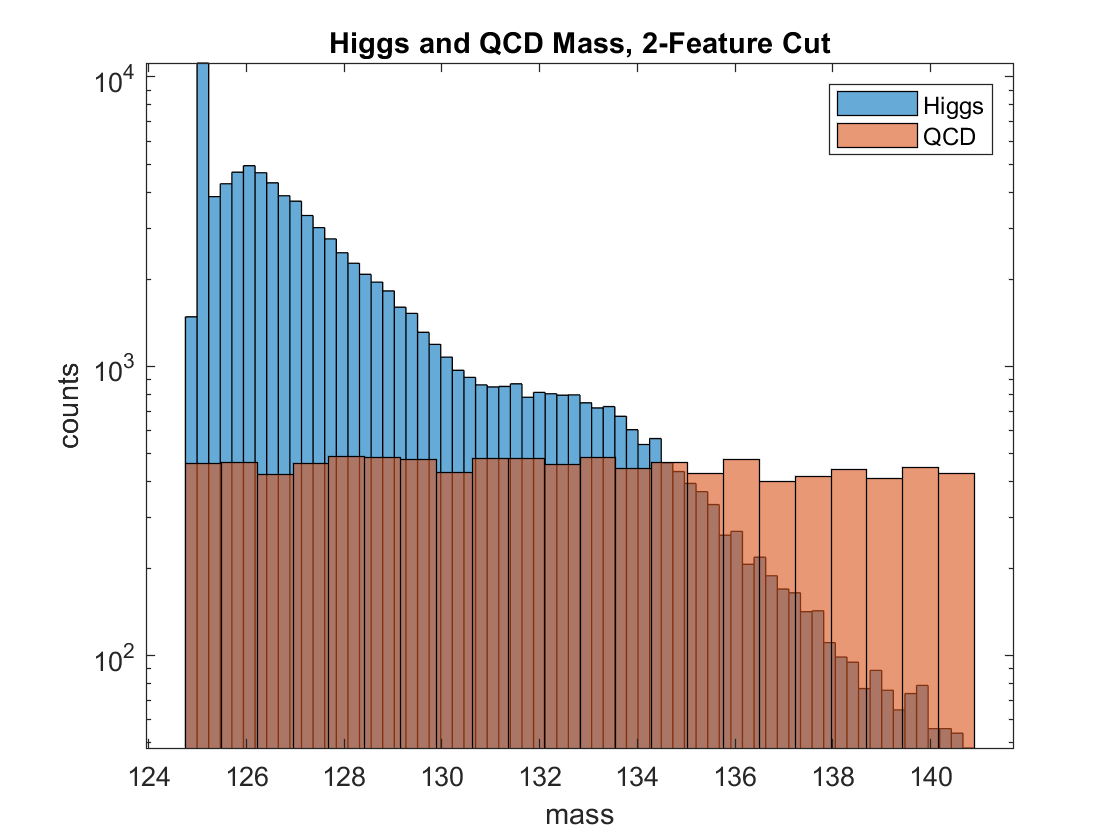

histogram(higgs(4,:),'BinLimits',[j(b),k(a)]);
hold on
histogram(qcd(4,:),'BinLimits',[j(b),k(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD Mass, 2-Feature Cut')
xlabel('mass')
ylabel('counts')
legend('Higgs','QCD')
hold off

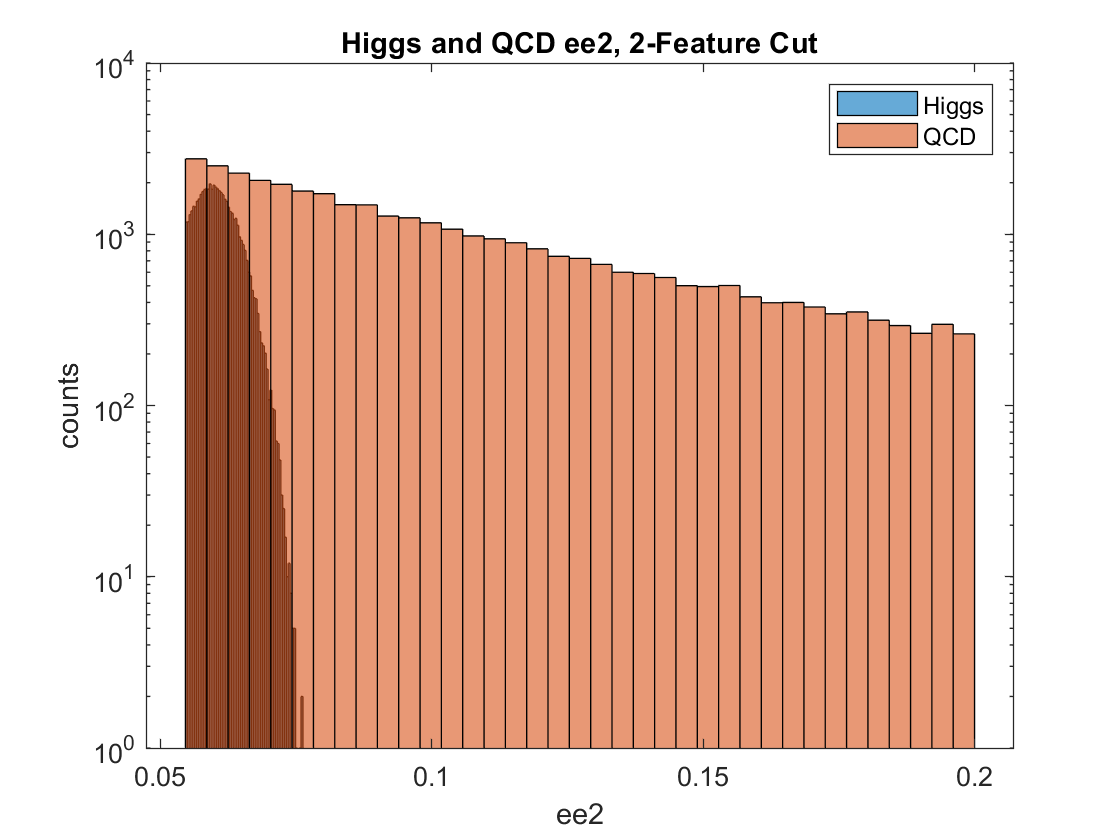

histogram(higgs(5,:),'BinLimits',[q(b),s(a)]);
hold on
histogram(qcd(5,:),'BinLimits',[q(b),s(a)]);
set(gca,'Yscale','log')
title('Higgs and QCD ee2, 2-Feature Cut')
xlabel('ee2')
ylabel('counts')
legend('Higgs','QCD')
hold off